% Extract autoencoder weights and display
W = auto.EncoderWeights;
disp(W);

  -0.065620083134553  -0.262162870078551  -0.190044180870032   0.009876167083419  -0.518858718265209  -0.534345292522450   0.452234594066627   0.099301899569045   0.420667511256761   0.129886248186711   0.432962726929405  -0.035979390668282   0.573018947226311   0.153945885271061  -0.652157580709341  -0.121962069151994   0.427675903672179   1.037712520125899   0.050309785050746   0.139388788562012   0.295319674182084
   0.116501234559551  -0.681688363301000  -0.687901894497504   0.215356589920184  -0.073822311800932  -0.335086520071070  -0.054966120402237   0.782288027411219   0.227005950961785   0.133574831063311  -0.073593137374433  -0.065094124958052   0.441973394697783   0.182994950991575  -0.636840548104806   0.134995840167812   0.561274768274248   0.297029787210725   0.370574586763130  -0.005027306695022   0.819709584916030
   0.137719069797582  -0.018781211126754   0.445297954016754  -0.386643559976811  -0.119327008229861  -0.213040990124168  -0.136768361256189  -0.2905615851924

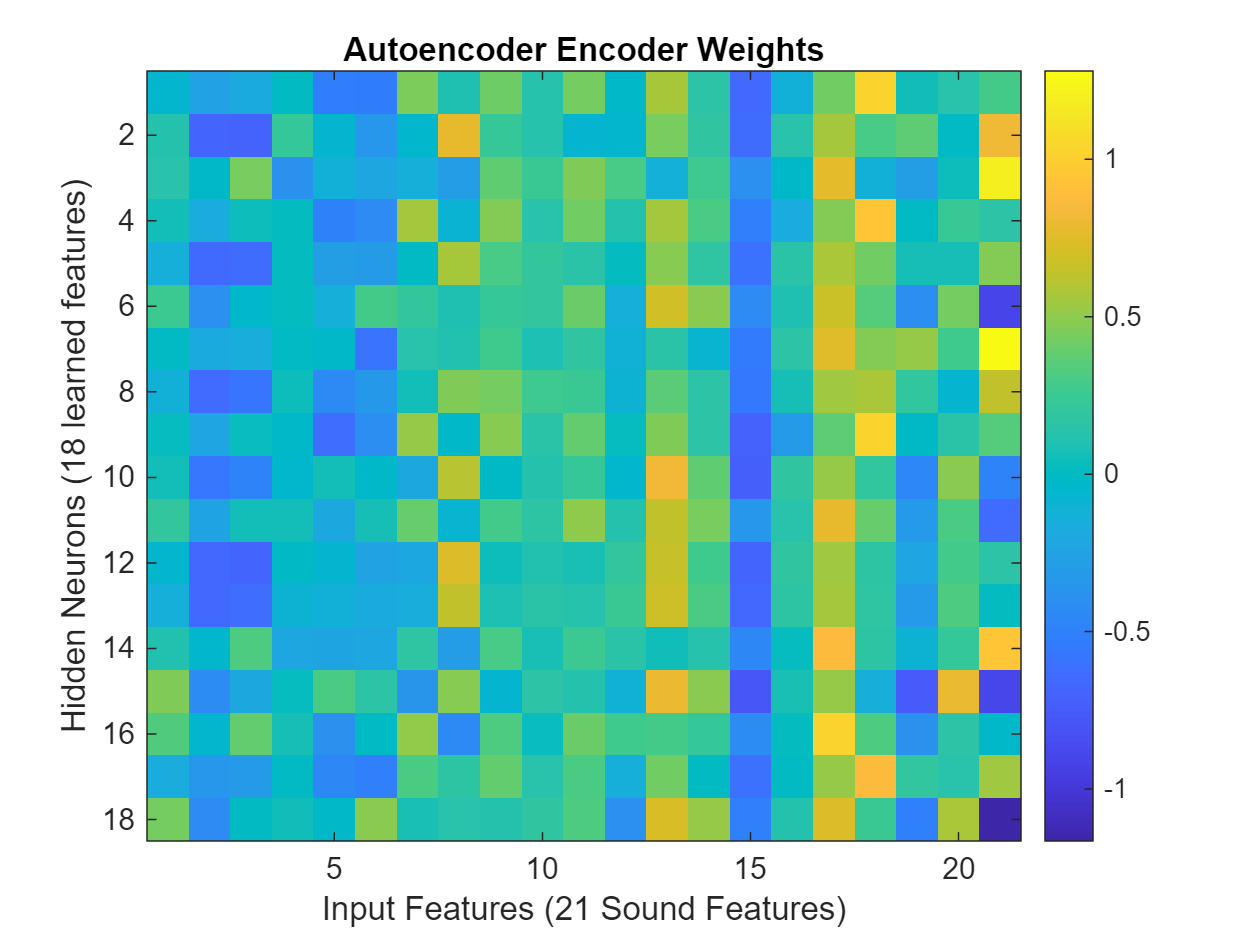

% Visualize the autoencoder weights
figure;
imagesc(W);
colorbar;
xlabel('Input Features (21 Sound Features)');
ylabel('Hidden Neurons (18 learned features)');
title('Autoencoder Encoder Weights');


featureNum = size(W, 2); overallWeight = zeros(featureNum,1); colW = [];

% colW = W(:, featureNum); overallWeight = sum(colW,1)

for featiter = 1:featureNum
    colW = W(:,featiter);
    overallWeight(featiter) = sum(colW,1);
end
disp(abs(overallWeight'));

   1.495690009141154   6.680073666327937   3.279925697446770   0.278452272602208   3.842977568037086   3.335095234990046   2.311232494946895   3.673915640387381   4.671270597867145   2.698891152567698   4.977906162721839   0.322822463300031   8.704610734224879   4.572904156386493  10.225067158932543   0.900003965717139  11.244222694959969   7.387755992848884   2.376365201247528   4.544459368860714   2.758677408207129



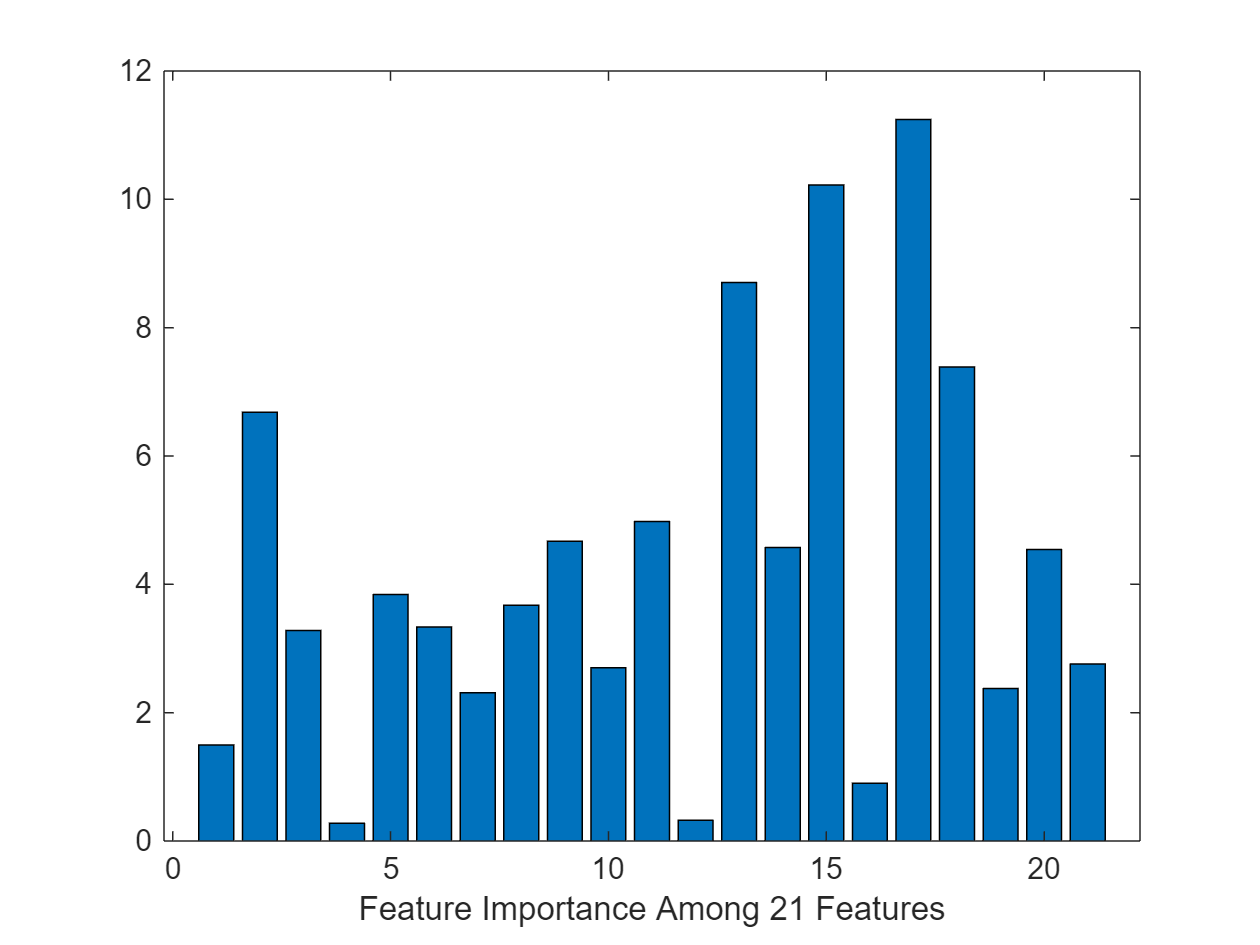


figure;
bar(abs(overallWeight'));
xlabel("Feature Importance Among 21 Features");

ylabel("Associated Weight"); 
